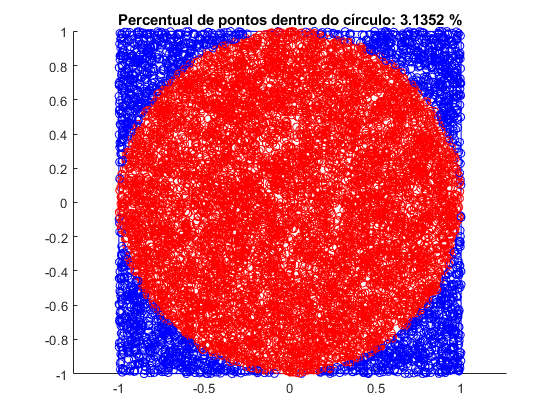

innerPoint = zeros(numPontos,1);

numPontos = 10000;
raio = 1;

pontoDentro = 0;
pontoFora = 0;

figure(1);
hold on;
axis equal;

rectangle('Position', [-raio, -raio, 2*raio, 2*raio], 'EdgeColor', 'b');

anguloCirculo = linspace(0, 2*pi);
xc = raio*cos(anguloCirculo);
yc = raio*sin(anguloCirculo);
plot(xc, yc, 'r-');

xp = -raio + 2*raio * rand(1, numPontos);
yp = -raio + 2*raio * rand(1, numPontos);

pontos = plot(xp, yp, 'ko'); 

distanciaPonto = sqrt(xp.^2 + yp.^2);

for i = 1:numPontos
    if distanciaPonto(i) <= raio
          plot(xp(i), yp(i), 'ro')
          pontoDentro = pontoDentro + 1;
    else
        plot(xp(i), yp(i), 'bo')
        pontoFora;
    end
    innerPoint(i) = pontoDentro;
end

porcentagem = 4*pontoDentro/numPontos;

title(['Percentual de pontos dentro do círculo: ', num2str(porcentagem),' %'])

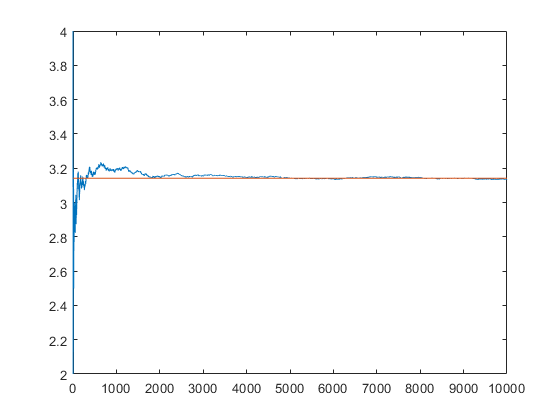


xx = [1:numPontos]';
figure
plot(xx,4*innerPoint./xx)
hold on
plot([1 numPontos],[1 1]*pi)